## Simulación basada en agentes del modelo SIR básico

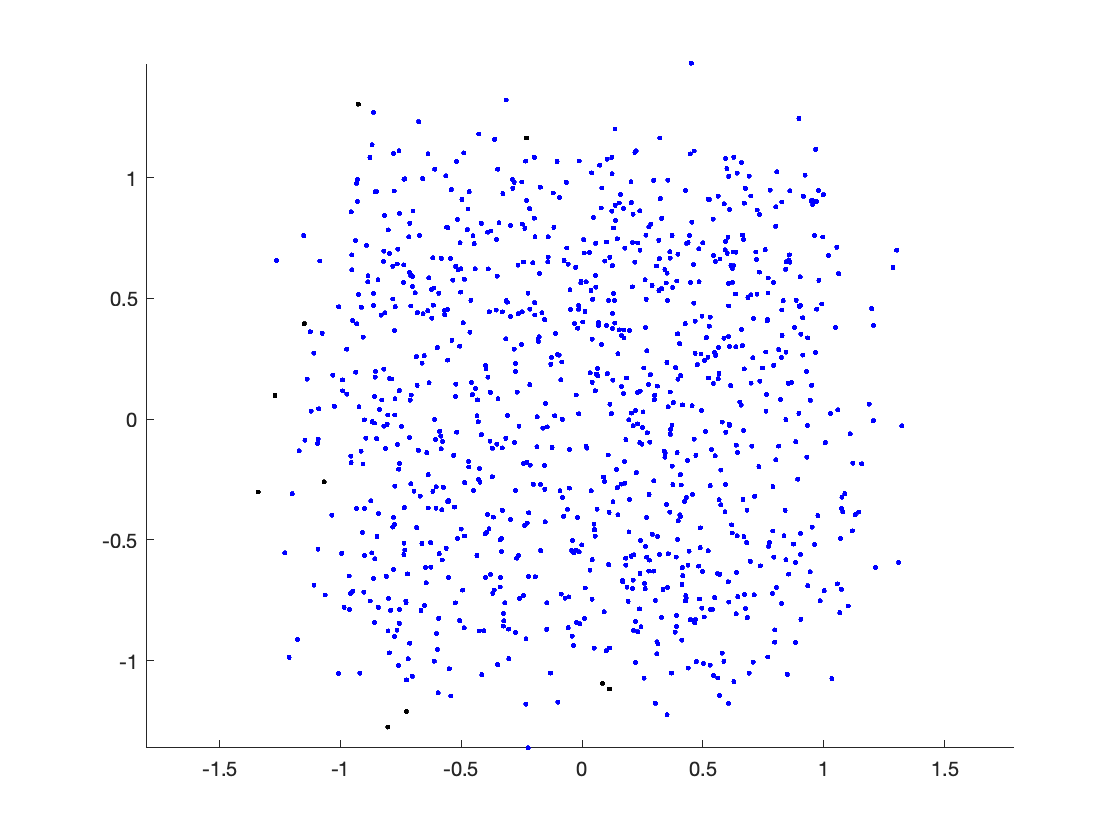

clear; 

Nt = 1000; % Población
Ni = 2; % Personas infectadas
Ns = Nt - Ni; % Personas normales
T = 500; % Tiempo de la simulación
Nr = 0; % Número de personas recuperadas

infradius = 0.05; % Radio de contagio
st = 0.02; % Parámetro
pd = makedist('Uniform', -1, 1); % Distribución espacial

tic_ = 100; % Longevidad de la enfermedad
clock_infe = zeros(tic_, Nt); % Matriz para almacenar todos los estados
ticAux = 0; % Auxiliar
clock_aux = 1; % Auxiliar
person.x = random(pd, 1, Nt); % Posiciones aleatorias
person.y = random(pd, 1, Nt); % //
person.status = zeros(1, Nt); % Estado de la persona (0 = normal, 1 = infectada, 2 = recuperada)
person.status(1:Ni) = 1; % Establecer el estado de las primeras Ni 
clock_infe(1, :) = person.status; % Copiar el primer estado
switch_IR = false; % Interruptor para iniciar la recuperación
%%% Condiciones iniciales
I(1) = Ni; 
S(1) = Ns;
R(1) = Nr; 
for i = 2:T
    % Movimiento
    rr = st * rand(1, Nt); 
    ph = 2 * pi * rand(1, Nt); 
    person.x = person.x + rr .* cos(ph); 
    person.y = person.y + rr .* sin(ph); 
    
    % Verificar los índices de las distancias entre infectados y normales menores que
    % el radio de contagio
    Xs = repmat(person.x(person.status == 0), Ni, 1); 
    Ys = repmat(person.y(person.status == 0), Ni, 1); 
    Xi = repmat(person.x(person.status == 1)', 1, Ns); 
    Yi = repmat(person.y(person.status == 1)', 1, Ns); 
    distances = (Xs - Xi).^2 + (Ys - Yi).^2; 
    indicesXi = max(distances < infradius^2, [], 1); 
    
    % Guardar el estado histórico
    clock_infe(i, :) = person.status; 

    % Nuevos infectados
    paux = person.status(person.status == 0); % Guardar los susceptibles
    paux(indicesXi) = 1; % Para aquellos dentro del radio, cambiar el estado a infectado 
    person.status(person.status == 0) = paux; % Actualizar el estado

    %% Cambio para iniciar la recuperación
    if i == tic_
        switch_IR = true;
    end
    
    % Buscar la matriz que tiene todas las recuperaciones y recuperar 
    if switch_IR
        ticAux = ticAux + 1;
        raux = find(clock_infe(ticAux, :) == 1);
        person.status(raux) = 2; 
    end
    % Nueva población
    Ni = length(person.status(person.status == 1)); 
    Ns = length(person.status(person.status == 0)); 
    Nr = length(person.status(person.status == 2)); 

    I(i) = Ni; 
    S(i) = Ns; 
    R(i) = Nr; 

    figure(1)
    scatter(person.x(person.status == 0), person.y(person.status == 0), '.', 'k'); hold on; axis equal;
    scatter(person.x(person.status == 1), person.y(person.status == 1), '.', 'r'); 
    scatter(person.x(person.status == 2), person.y(person.status == 2), '.', 'b'); hold off
    pause(0.001)
end

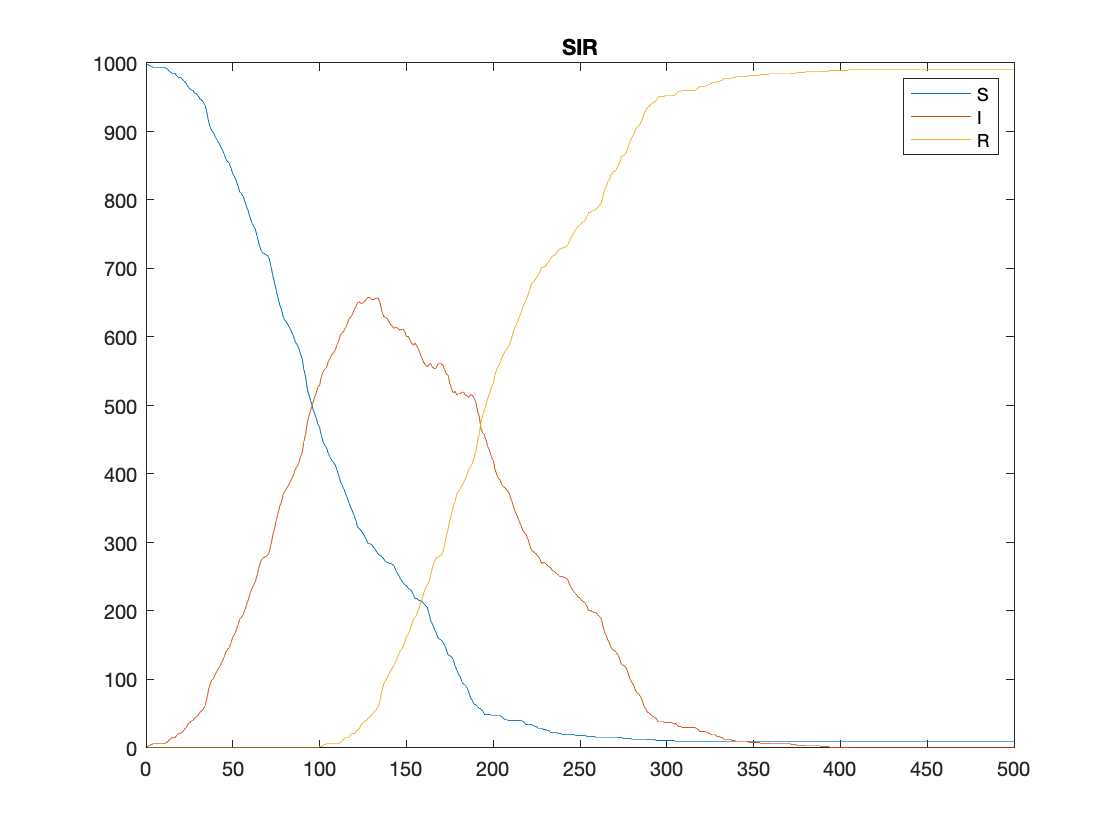


plot(S)
hold on
plot(I)
plot(R)
title('SIR')
legend('S', 'I', 'R')
hold off